# Inverted Pendulum

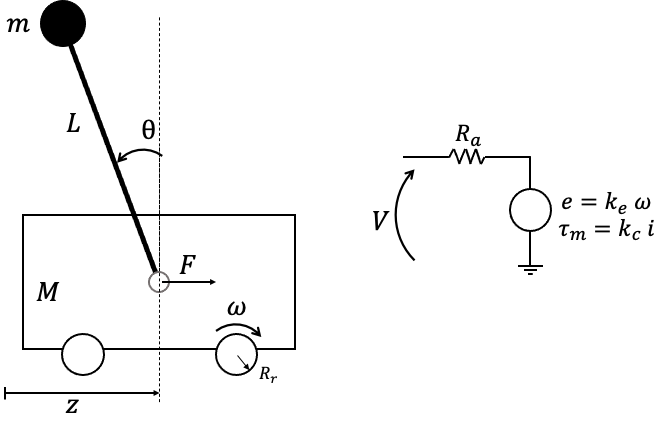

close all;

% These variables are for MATLAB usage only. Simulinks has its own copy in the mask of the system.
m  = 2;     % Damped mass [kg]
M  = 10;    % Mass of the cart [kg]
L  = 1;     % Length of the beam [m]
Rr = 0.1;   % Radius of cart's wheels [m]
Ke = 2;     % Parameter of the DC motor
Kc = 2;     % Parameter of the DC motor
Ra = 10;    % Armature resistance of the DC motor [Ohm]
g  = 9.81;  % Gravity

z0 = 0;             % Initial position of the cart
theta0 = 0.2;       % Initial orientation of the beam
z_dot0 = 0;         % Initial linear speed of the cart
thetda_dot0 = 0;    % Initial angular speed of the beam

### Dynamical model of the system

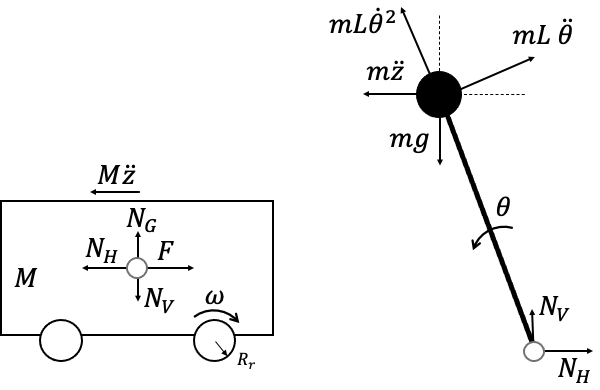

**DC Motor:**


$$F=\frac{\tau_m }{R_r }=\frac{k_c }{R_a R_r }\left(V-\frac{k_e }{R_r }\;\dot{z} \right)$$


**Balance on the cart:**


$$M\;\dot{z} +N_H =F$$
 

**Balance on the beam:**


$$\begin{array}{l}
M\;\ddot{z} +m\;L\dot{\;\theta^2 } \;\sin \;\theta -m\;L\;\ddot{\theta} \;\;\cos \;\theta -N_H =0\\
m\;L^2 \;\ddot{\;\theta \;} -m\;L\;\ddot{z} \;\cos \;\theta -m\;g\;L\;\sin \;\theta =0
\end{array}$$


**Combining them we obtain:**


$$\begin{array}{l}
\ddot{\;\vartheta \;} =\frac{\ddot{z} }{L}\;\cos \;\theta +\frac{g}{L}\sin \;\theta \\
\left(M+m\right)\ddot{z} +m\;L\dot{\;\theta^2 } \;\sin \;\theta -m\;L\;\ddot{\theta} \;\cos \;\theta =\frac{k_{c\;} }{{\;R}_a R_r }\;V-\frac{k_c k_e }{\;R_a R_r^2 }\dot{z} 
\end{array}$$


which leads to


$$\left\{ \begin{array}{l}
\ddot{z} =  \frac{1}{M + m -m \cos^2 \theta  } \bigg[ - \frac{k_c \, k_e}{ R_a \, R_r^2 } \, \dot{z} - mL \dot{\theta}^2 \sin\theta   + mg \sin \theta  
 \cos\theta  + \frac{k_c }{ R_a \, R_r} \, V \bigg] \\
\ddot{\theta} =  \frac{g}{L} \sin \theta +  \frac{\cos \theta}{L \big( M + m -m \cos^2 \theta  \big)} \bigg[ - \frac{k_c \, k_e}{ R_a \, R_r^2 } \, \dot{z} - mL \dot{\theta}^2 \sin\theta   + mg \sin \theta  
 \cos\theta  + \frac{k_c }{ R_a \, R_r} \, V \bigg]

\end{array}\right.$$


Now we must switch to a **state space form:** 

- States: $x={\left\lbrack x_1 ,x_2 ,x_3 ,x_4 \right\rbrack }^T ={\left\lbrack z,\dot{z} ,\vartheta ,\dot{\vartheta} \;\right\rbrack }^T$ 

- Input: $u=\left\lbrack \;V\;\right\rbrack$


$$\left\{ \begin{array}{l}
\dot{x}_1 = x_2 \\
\dot{x}_2 = \frac{1}{M + m -m \cos^2 x_3 } \bigg[ - \frac{k_c \, k_e}{ R_a \, R_r^2 } \, x_2 - mL x_4^2 \sin x_3   + mg \sin x_3 
 \cos x_3  + \frac{k_c }{ R_a \, R_r} \, u \bigg] \\
\dot{x}_3 = x_4 \\
\dot{x}_4 =  \frac{g}{L} \sin x_3 +  \frac{\cos x_3}{L \big( M + m -m \cos^2 x_3 \big)} \bigg[ - \frac{k_c \, k_e}{ R_a \, R_r^2 } \, x_2 - mL x_4^2 \sin x_3   + mg \sin x_3 
 \cos x_3  + \frac{k_c }{ R_a \, R_r} \, u \bigg] \\
\end{array}\right.$$


## 1a) Linearization (by hand)

*Linearize the system around the origin (unstable equilibrium), i.e. *${\left\lbrack z,\dot{\;z} ,\;\vartheta ,,\dot{\vartheta} \;\right\rbrack }^T ={\left\lbrack 0,0,0,0\right\rbrack }^T$*, *$\bar{u} =\bar{V} =0$


$$\left\{ \begin{array}{l}
\delta \dot{x}_1 = \delta x_2 \\
\delta \dot{x}_2 = - \frac{k_e k_c}{M \, R_a \, R_r^2 } \, \delta x_2 + \frac{mg}{M} \delta x_3 + \frac{k_c }{M \,  R_a \, R_r} \, \delta u \\
\delta \dot{x}_3 = \delta x_4 \\
\delta \dot{x}_4 = -\frac{k_e \, k_c}{L M \, R_a \, R_r^2 } \, \delta x_2 + \frac{(m+M)g}{L M}\delta x_3 + \frac{k_c }{L M \,  R_a \, R_r} \, \delta u \\
\end{array}\right.$$


which leads to the following system:

A = [   0,              1,                  0,              0;
        0,   -(Ke*Kc)/(M*Ra*Rr^2),        m*g/M,            0;
        0,              0,                  0,              1;
        0,   -(Ke*Kc)/(L*M*Ra*Rr^2),   (m+M)*g/(L*M),       0;  ]

A =          0    1.0000         0         0
         0   -4.0000    1.9620         0
         0         0         0    1.0000
         0   -4.0000   11.7720         0


    
B = [   0;          Kc/(M*Ra*Rr);           0;         Kc/(L*M*Ra*Rr) ]

B =          0
    0.2000
         0
    0.2000


C = [ 1, 0, 0, 0;
      0, 0, 1, 0 ];
D = zeros(2, 1);

## 1) Linearization (using Simulink)

*Now try to use the Time-Based Linearization block to compute the linearized system.*

This is the suggested way, since we nonetheless have to implement the nonlinear model in Simulink: **use the Time-Based Linearization Block!**

open('Pendulum_Linearization.slx');

sim('Pendulum_Linearization.slx');
Pendulum_Linearization_Timed_Based_Linearization.a

ans =          0    1.0000         0         0
         0   -4.0000    1.9619   -0.0000
         0         0         0    1.0000
         0   -4.0000   11.7718   -0.0000


Pendulum_Linearization_Timed_Based_Linearization.b

ans =          0
    0.2000
         0
    0.2000


⚠️**Remark****: **If instead of selecting as outputs all the states of the system we select the real outpus ($x\;\textrm{and}\;\vartheta$), the states of the system identified using the Time-Based Linearization block could be different from the ones of the real system!

## 2) Analyze the system and enlarge with integrators

First, let us analyze the the linearized system

sys_ol = ss(A, B, C, D);
pole(sys_ol)

ans =          0
   -4.7362
   -2.5337
    3.2699


tzero(sys_ol)


ans =

  0×1 empty double column vector



Then, place integrators on the outputs' tracking errors to guarantee robust asymptotic zero-error tracking of constant references.

**Remark**: Since there is only one control variable ($m=1$) we can place at most one integrator.

Assume that we want to give constant references either to the position $z$, or to the angle $\vartheta$, or both. To do so, we need to place integrators.

-  $p\le m$   NOT SATISFIED  $\Longrightarrow$  We can control at most $m=1$ outputs. **We choose to control the position **$z$**.**

-  No derivative action (no invariant zeros in the origin)

Recall that, when we select an output, we need to check the invariant zeros for the "restricted" system


$$\left\{ \begin{array}{l}
\delta \dot{x} = A \, \delta x + B \, \delta u \\
\delta y_1 = C_1 \, \delta x + D_1 \, \delta u = \delta x_1 \end{array}
\right.$$


To check the position of invariant zeros we can use the function `tzero. `

tzero(A, B, C(1, :), D(1, :)) % we have two zeros now

ans =    -3.1321
    3.1321


No invariant zero in the origin $\Longrightarrow$ OK

⚠️**Remark****: We cannot control **$\vartheta \;$** to constant references! **(This consideration is quite intuitive from a pyshical point of view)

tzero(A, B, C(2, :), D(2, :))

ans = 	1.0e+-15 *

   -0.6351
         0


### Place the integrator on the first output

$\dot{\eta} =y_1^0 -y_1 =\delta y_1^0 -\delta y_1 =\delta y_1^0 -C_1 \delta x$    C1 is the first row of C


$$\delta \dot{x} =A\delta x+B\;\delta u$$


Therefore the enlarged system reads as


$$\dot{\tilde{x} } =\left\lbrack \begin{array}{cc}
A & 0\\
-C_1  & 0
\end{array}\right\rbrack \tilde{x} +\left\lbrack \begin{array}{c}
B\\
0
\end{array}\right\rbrack \delta u+\left\lbrack \begin{array}{c}
0\\
I
\end{array}\right\rbrack \delta y^0$$


A_tilde = [ A,          zeros(4, 1);
            -C(1, :),   0 ];
B_tilde = [ B;
            0 ];
M_tilde = [ zeros(4, 1);
            1               ];

## 3) LQ Controller Design

*Considering the same scheme adopted in the previous point, implement an *${\textrm{LQ}}_{\infty }$ controller*. *

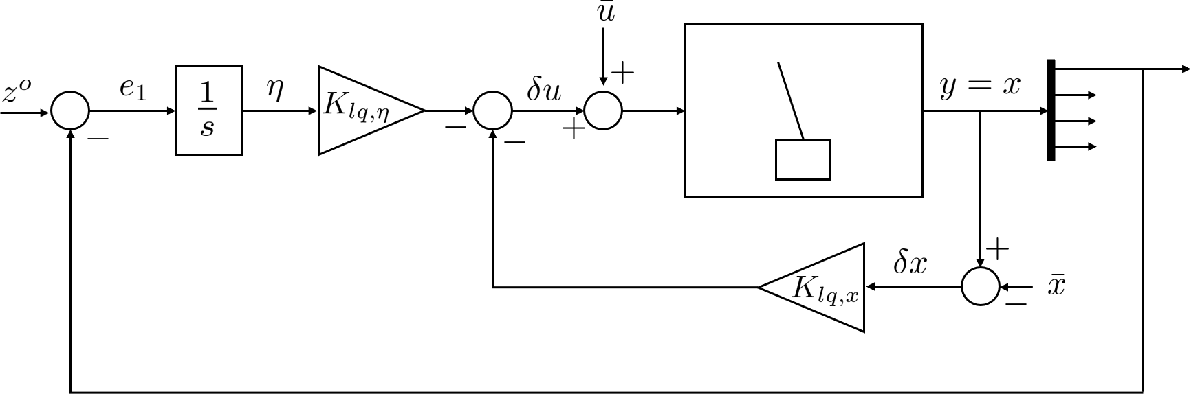

Find the ${\textrm{LQ}}_{\infty }$ control law for the enlarged system $\;\Longrightarrow$   same scheme, different way to compute the gains

Function: `lqr(A, B, Q, R)`

For the time being, we assume  

Q_lq = diag([0.1, 10, 0.1, 10, 1]); % il quinto stato è quello dell 'integratore
% inoltre abbiamo penalizzato più gli stati legati alle velocità perchè
% potrebbero portare il sitema fuori dal range di validità del modello lineare
R_lq = 0.1;

To implement the ${\textrm{LQ}}_{\infty }$ we need to check that

- The pair $\left(\tilde{A} ,\tilde{B} \right)$is reachable  $\Longrightarrow$  OK

rank(ctrb(A_tilde, B_tilde))

ans = 5

- The pair $\left(\tilde{A} ,{\tilde{C} }_q \right)$is observable, where $C_q^T \;C_q =Q\;\;\Longrightarrow$  OK

Cq = sqrt(Q_lq); % We can do this because Q_lq is diagonal!!
rank(obsv(A_tilde, Cq))

ans = 5

Since the ${\mathrm{LQ}}_{\infty }$ law is stabilizing, we can compute the corresponding gain by solving the steady-state Riccati equation. 

We can do so using the `lqr` command:

K_lq = lqr(A_tilde, B_tilde, Q_lq, R_lq)

K_lq =   -14.7078  -54.0451  298.5856   92.6862    3.1623


Eventually we can partition the gain `K_lq` as 

K_lqx   = K_lq(:, 1:4); % gains associated with the state of the system
K_lqeta = K_lq(:, 5); % gain associated with the integrator

### Implementation

open('Pendulum_LQ.slx');

## 4) LQG (LQ + Kalman Filter)

*Design and implement a Kalman Filter to estimate the states of the system, assuming that we only measure the position of the cart *$z$* and the angle of the beam.*

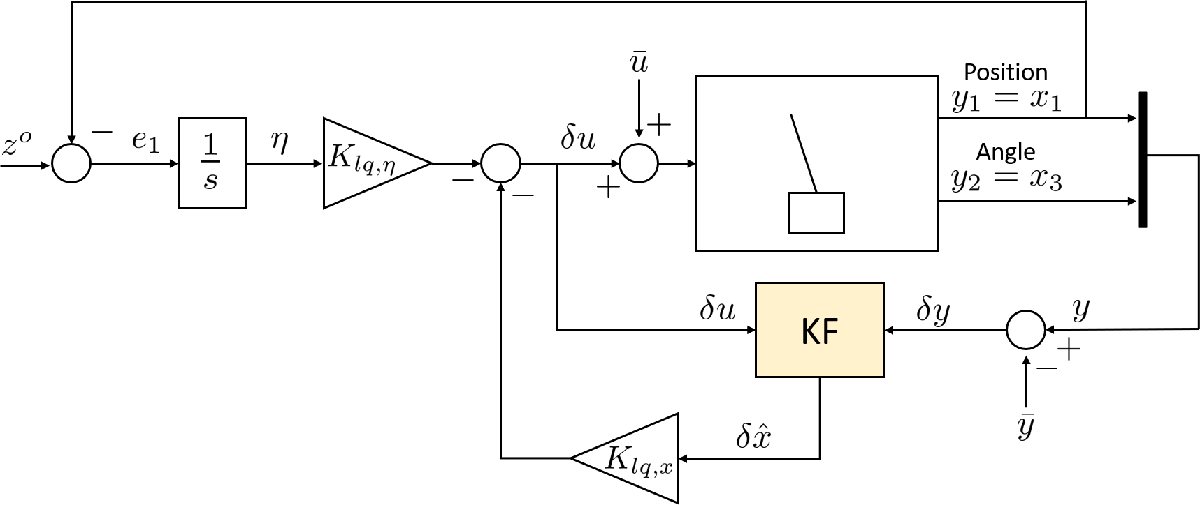

**Remark****:** We only need to estimate $\delta x=\left\lbrack \begin{array}{cccc}
\delta x_1  & \delta x_2  & \delta x_3  & \delta x_4 
\end{array}\right\rbrack \ldotp$ The state $\eta$ is known and does not neet to be estimated. Therefore we design the Kalman Filter for the following system:


$$\left\{ \begin{array}{l} 
\delta \dot{x} = A \, \delta x + B \, \delta u + \nu_x \\
\delta y = C \, \delta x + \nu_y
\end{array}\right.
\qquad \qquad  \begin{array}{l} \nu_x \,\tilde\, \text{WGN}(0, Q_{kf}) \\ \nu_y \,\tilde\, \text{WGN}(0, R_{kf})  \end{array}$$


Q_kf = diag([0.1, 1, 0.1, 1]);  % The models of state 1 (z) and state 3 (theta) are the most reliable
R_kf = 0.1;                     % We trust the measurements more than the linearized model

### Observability check

- The pair $\left(A,B_{q\_\textrm{kf}}^T \right)$ must be reachable  $\Longrightarrow$  OK

B_qkf = sqrt(Q_kf); % We can do this because Q_kf is diagonal!!

rank(ctrb(A, B_qkf))

- The pair $\left(A,C\right)$ must be observable  $\Longrightarrow$  OK

rank(obsv(A, C))

The dynamics equation of the Kalman Filter is


$$\delta \overset{\circ }{\hat{x} } =A\;\delta \hat{x} +B\;\delta u+L_{\textrm{kf}} \left(\delta y-C\;\delta \hat{x} \right)=\left(A-L_{\textrm{kf}} \;C\right)\delta \hat{x} +\left\lbrack \begin{array}{cc}
B & L_{\textrm{kf}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\delta u\\
\delta y
\end{array}\right\rbrack$$


Where the gain $L_{\textrm{kf}}$ is the retrieved solving the steady-state Riccati Equation

L_kf = lqr(A.', C.', Q_kf, R_kf).'

We also need to initialize the Kalman Filter, specifying an initial guess, e..g. $\delta \hat{x} ={\left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 0
\end{array}\right\rbrack }^T$

delta_x0_hat = zeros(4, 1);

ans = 4


A_kf = A - L_kf * C;

ans = 4

B_kf = [ B, L_kf ];
C_kf = eye(4);
D_kf = zeros(4, 3)

### Implementation

open('Pendulum_LQG.slx');

L_kf =     1.2670    0.2692
    0.3389    1.6692
    0.2692    6.7414
    0.4863   22.2595


D_kf =      0     0     0
     0     0     0
     0     0     0
     0     0     0


## Final considerations

- Remember that the presence of **input saturations can destroy the asymptotic stability guarantees**!

- The **amplitude of the measurement noise can harm the closed-loop stability** as well, if the underlying system is unstable and highly non-linear!